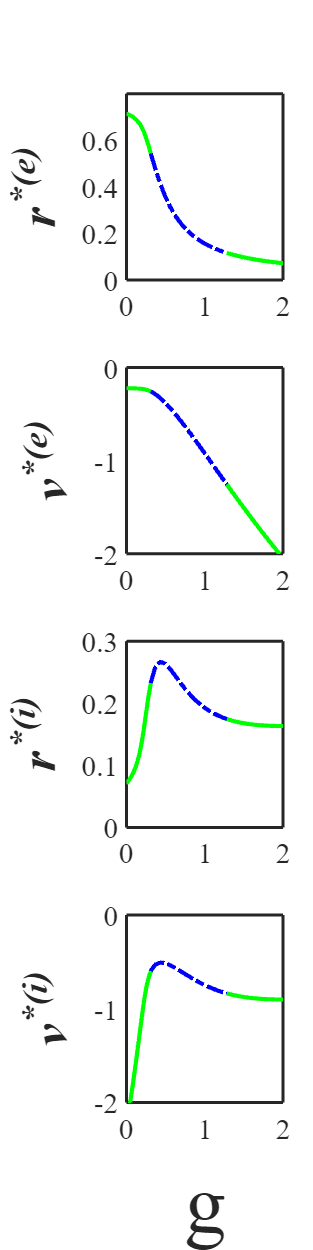

load('Hopf_Bif_COBA_2.mat')

% Set default properties for the current script
set(0, 'DefaultAxesFontName', 'Times New Roman');
set(0, 'DefaultTextFontName', 'Times New Roman');


g1_COBA2 = g_COBA2(1:24);
g2_COBA2 = g_COBA2(24:41);
g3_COBA2 = g_COBA2(41:end);
re1_COBA2 = re_COBA2(1:24);
re2_COBA2 = re_COBA2(24:41);
re3_COBA2 = re_COBA2(41:end);
ri1_COBA2 = ri_COBA2(1:24);
ri2_COBA2 = ri_COBA2(24:41);
ri3_COBA2 = ri_COBA2(41:end);
ve1_COBA2 = ve_COBA2(1:24);
ve2_COBA2 = ve_COBA2(24:41);
ve3_COBA2 = ve_COBA2(41:end);
vi1_COBA2 = vi_COBA2(1:24);
vi2_COBA2 = vi_COBA2(24:41);
vi3_COBA2 = vi_COBA2(41:end);


figure('Units', 'inches', 'Position', [0, 0, 6, 24]); % 7 pulgadas de ancho, 7 pulgadas de alto

% Primer subplot
subplot(4, 1, 1);
plot(g1_COBA2, re1_COBA2, '-g', 'LineWidth', 2); % Línea verde sólida para y1
hold on;
plot(g2_COBA2, re2_COBA2, '-.b', 'LineWidth', 2); % Línea azul con puntos para y2
hold on;
plot(g3_COBA2, re3_COBA2, '-g', 'LineWidth', 2);
hold off;
set(gca, 'FontSize', 14);
ylabel('r^*^{(e)}', 'FontSize', 25, 'FontAngle', 'italic', 'FontWeight', 'bold');
xlim([0 2]);
ylim([0 0.8]);
set(gca, 'LineWidth', 1.5); % Establece el ancho de línea de los eges

% Segundo subplot
subplot(4, 1, 2);
plot(g1_COBA2, ve1_COBA2, '-g', 'LineWidth', 2); % Línea verde sólida para y1
hold on;
plot(g2_COBA2, ve2_COBA2, '-.b', 'LineWidth', 2); % Línea azul con puntos para y2
hold on;
plot(g3_COBA2, ve3_COBA2, '-g', 'LineWidth', 2); 
hold off;
set(gca, 'FontSize', 14);
ylabel('v^*^{(e)}', 'FontSize', 25, 'FontAngle', 'italic', 'FontWeight', 'bold');
xlim([0 2]);
ylim([-2 0]);
set(gca, 'LineWidth', 1.5); % Establece el ancho de línea de los eges

% Tercer subplot
subplot(4, 1, 3);
plot(g1_COBA2, ri1_COBA2, '-g', 'LineWidth', 2); % Línea verde sólida para y1
hold on;
plot(g2_COBA2, ri2_COBA2, '-.b', 'LineWidth', 2); % Línea azul con puntos para y2
hold on;
plot(g3_COBA2, ri3_COBA2, '-g', 'LineWidth', 2);
hold off;
set(gca, 'FontSize', 14);
ylabel('r^*^{(i)}', 'FontSize', 25, 'FontAngle', 'italic', 'FontWeight', 'bold');
xlim([0 2]);
ylim([0 0.3]);
set(gca, 'LineWidth', 1.5); % Establece el ancho de línea de los eges

% Cuarto subplot
subplot(4, 1, 4);
plot(g1_COBA2, vi1_COBA2, '-g', 'LineWidth', 2); % Línea verde sólida para y1
hold on;
plot(g2_COBA2, vi2_COBA2, '-.b', 'LineWidth', 2); % Línea azul con puntos para y2
hold on;
plot(g3_COBA2, vi3_COBA2, '-g', 'LineWidth', 2);
hold off;
set(gca, 'FontSize', 14);
ylabel('v^*^{(i)}', 'FontSize', 25, 'FontAngle', 'italic', 'FontWeight', 'bold');
xlim([0 2]);
ylim([-2 0]);
set(gca, 'LineWidth', 1.5); % Establece el ancho de línea de los eges

xlabel('g', 'FontSize', 40);

% Megora la presentación de la figura
set(gcf, 'Color', 'w'); % Establece el color de fondo de la figura a blanco

% Alternativamente, puedes usar:
exportgraphics(gcf, 'COBA2Hopf.png', 'Resolution', 300); % Guarda con mayor resolución